# Calcium plot for Identifying stimuli specifc cell response

this code is to plot calcium imaging signals. What's required is a csv file containing intensity of ROIs. This code is modified based on CalciumPlot. Last edited on May 3 2025

#### Read Table and plot heatmap

stimuli = '1_pinch.csv'

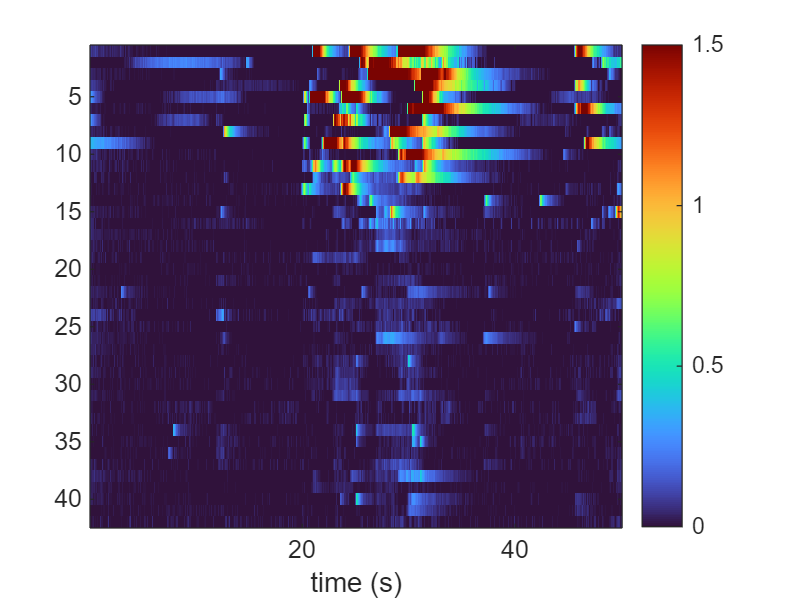

stimuli = '2_AITC.csv'

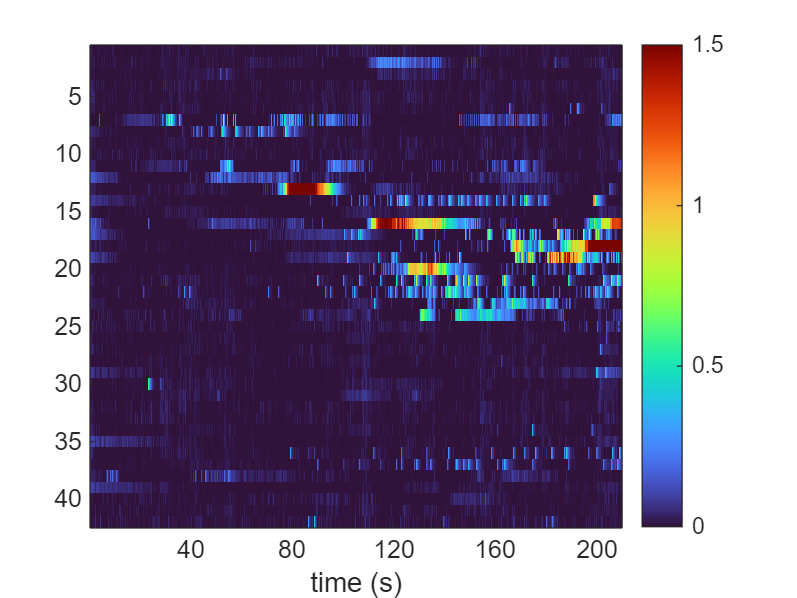

stimuli = '3_capsaicin.csv'

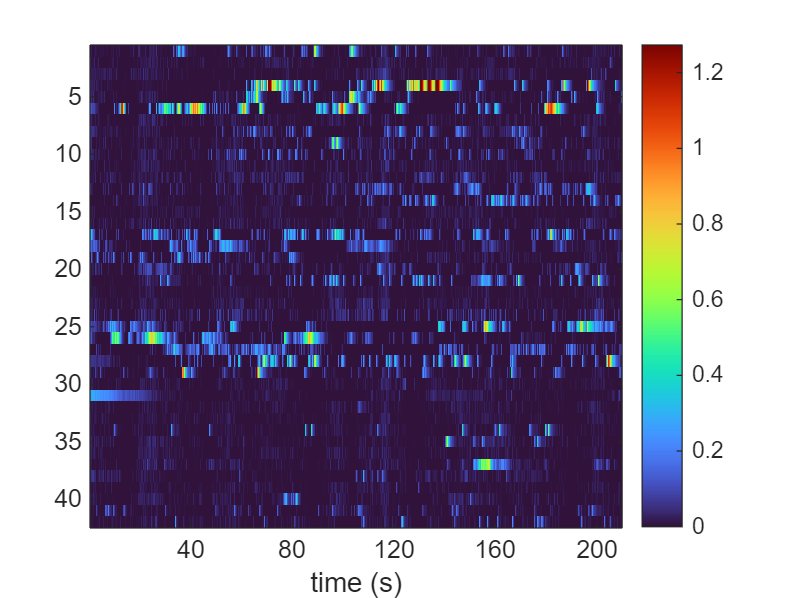

stimuli = '4_pinch.csv'

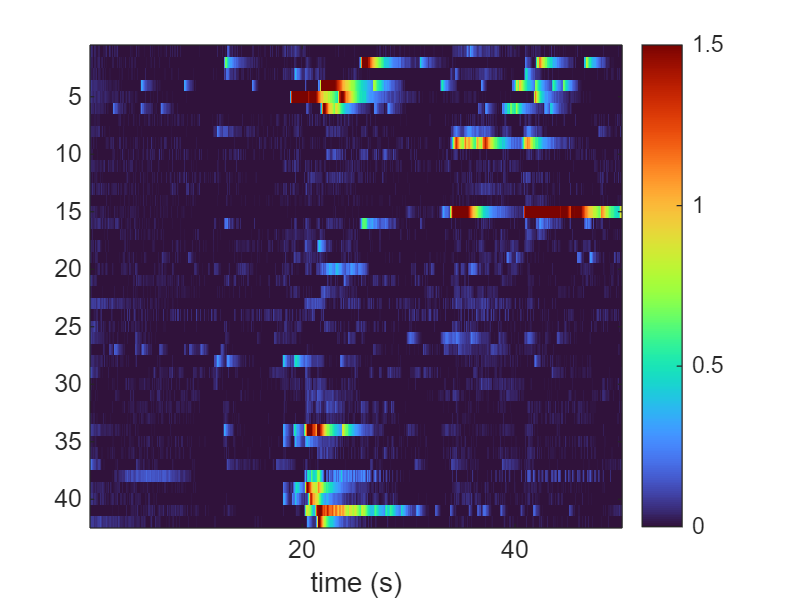

close all
clearvars -except path

%fps = 10; % frequency in Hz, change this when using different settings

% if exist('path', 'var') == 0 || isempty(path) || ~ischar(path)
%     [filename,path] = uigetfiles("\research.files.med.harvard.edu\Neurobio\GintyLab\Xiao\Rig\calcium\*.csv");
% else
%     [filename, path] = uigetfile(fullfile(path,'*.csv'));
% end

[fileNames, pathName] = uigetfile('\\research.files.med.harvard.edu\Neurobio\GintyLab\Xiao\Rig\calcium\*.csv', 'Select CSV files', 'MultiSelect', 'on');
%[zipFile, zipPath] = uigetfile('\\research.files.med.harvard.edu\Neurobio\GintyLab\Xiao\Rig\calcium\*.zip', 'Select ROI file','MultiSelect', 'on');
% initialPlot is a function for us to get a first and general idea of how
% the data looks like. Bleach correction is only suggested when the
% calcium spikes are short or when the recording session is longer than
% 120s


datatable = struct([]);


% Loop through each selected file and read it
for i = 1:length(fileNames)
    fullFileName = fullfile(pathName, fileNames{i});
    stimuli = fileNames{i}
    cur_data = readtable(fullFileName);      % or csvread/fullfile depending on format
    datatable(i).name = stimuli;
    datatable(i).Oridata = cur_data(:,startsWith(cur_data.Properties.VariableNames, 'Mean'));
    if ~contains(stimuli,'pinch')
        datatable(i).framerate = 5; %Hz CHANGE FOR DIFFERENT SETTING
        fps = 5;
    else
        datatable(i).framerate = 10;
        fps = 10;
    end
    normDeltaF = initialProcess(pathName, fileNames{i}, fps, 'bleach correction', 6, 0.975);
    NewnormDeltaF = normDeltaF(:,:) - mean(normDeltaF(1:100,:)); %baseline fixed to be 100 frames
    datatable(i).dataABC = NewnormDeltaF(:,:);%,27:end); %REMOVE SOME DUPLICATES
    % stds = std(normDeltaF);
    % [~, idx] = sort(stds);
    % sorted_normDeltaF = normDeltaF(:,idx)
    % datatable(i).sortedABC = sorted_normDeltaF;

    % xCols = cur_data{1,startsWith(cur_data.Properties.VariableNames, 'X')}';
    % yCols = cur_data{1,startsWith(cur_data.Properties.VariableNames, 'Y')}';
    % cell_label = table((1:length(xCols))',xCols,yCols,'VariableNames', {'CellIndex', 'Xloc','Yloc'})
    % cell_label.dataABC = num2cell(normDeltaF,1)';
    % datatable(i).celllabel = cell_label;
    % 
    % 
    % %Look at ROIs
    % cur_zipFilePath = fullfile(zipPath, zipFile{i});
    % [zipFolder, baseName, ~] = fileparts(cur_zipFilePath);
    % outputFolder = fullfile(zipFolder, baseName);
    % unzip(cur_zipFilePath, outputFolder);
    % roiFiles = dir(fullfile(outputFolder, '*.roi'));
    % %numROIs = length(roiFiles);
    % datatable(i).cellroi = roiFiles;
end


%normDeltaF = initialProcess(path, filename, fps, 'bleach correction', 6, 0.975);
% normDeltaF = initialProcess(path, filename, fps);

% for the thermal stimulation, split them into 10 files and save. Make sure you use
% the same stimulation file: starting from 35, ending at 55 C
% if size(normDeltaF, 1) == 9000
%     temperature = [35, 25, 20, 40, 15, 45, 10, 50, 5, 55];
%     T = readtable(fullfile(path, filename));
%     n = size(T, 1)/10;
%     for i = 1:10
%         Tsplit = T(1+n*(i-1):i*n,:);
%         writetable(Tsplit, fullfile(path, ['peltier_', num2str(temperature(i)),'C.csv']));
%     end
% end

% % To compare if there is any overlap of the cell label
% canvasSize = [700,1024];
% n = length(datatable);
% nameList = {datatable.name};
% centroidOverlapTable = cell(n, n);
% centroidNonOverlapTable = cell(n, n);
% radiusThreshold = 5;  % pixels
% 
% for i = 1:n
%     Xi = datatable(i).celllabel.Xloc;
%     Yi = datatable(i).celllabel.Yloc;
%     coords_i = [Xi, Yi];
%     indices_i = datatable(i).celllabel.CellIndex;
% 
%     for j = 1:n
%         if i == j
%             centroidOverlapTable{i,j} = [];  % Skip self-comparison
%             continue;
%         end
% 
%         Xj = datatable(j).celllabel.Xloc;
%         Yj = datatable(j).celllabel.Yloc;
%         coords_j = [Xj, Yj];
% 
%         % Compute pairwise distance matrix
%         D = pdist2(coords_i, coords_j);
% 
%         % For each point in i, see if there's any point in j within radius
%         isOverlapping = any(D <= radiusThreshold, 2);
% 
%         % Get CellIndex values from i that overlap with any in j
%         overlappingIndices = indices_i(isOverlapping);
%         nonOverlappingIndices = indices_i(~isOverlapping);
% 
%         centroidOverlapTable{i,j} = overlappingIndices;  % each row is having cellindex of the rowname file
%         centroidNonOverlapTable{i,j} = nonOverlappingIndices;
%     end
% end
% 
% % Convert to labeled table
% centroidOverlapTable = cell2table(centroidOverlapTable, ...
%     'VariableNames', nameList, 'RowNames', nameList);
% centroidNonOverlapTable = cell2table(centroidNonOverlapTable, ...
%     'VariableNames', nameList, 'RowNames', nameList);
% 
% figure; hold on; axis equal;
% set(gca, 'YDir', 'reverse');
% title('All ROIs from all datasets (highlighting overlapping centroids)');
% xlim([1, canvasSize(2)]);
% ylim([1, canvasSize(1)]);
% 
% for i = 1:n
%     % Collect overlapping cell indices for this dataset
%     otherCols = setdiff(1:n, i);
% 
%     % Select cells from row i, columns other than i
%     entries = centroidOverlapTable{i, otherCols};  % <- USE curly braces {} here to extract contents
% 
%     % Now 'entries' is a 1×(n-1) cell array
%     entries = entries(~cellfun('isempty', entries));  % filter non-empty cells
% 
%     % Safely concatenate and get unique
%     if ~isempty(entries)
%         allOverlapping = unique(vertcat(entries{:}));
%     else
%         allOverlapping = [];
%     end
% 
%     roiFiles = datatable(i).cellroi;
%     numROIs = length(roiFiles);
% 
%     for k = 1:numROIs
%         roi = ReadImageJROI(fullfile(roiFiles(k).folder, roiFiles(k).name));
%         isOverlap = ismember(k, allOverlapping);
% 
%         % Get boundary coordinates
%         if strcmpi(roi.strType, 'Oval')
%             bounds = roi.vnRectBounds;  % [y1 x1 y2 x2]
%             cx = (bounds(2) + bounds(4))/2;
%             cy = (bounds(1) + bounds(3))/2;
%             rx = abs(bounds(2) - bounds(4))/2;
%             ry = abs(bounds(1) - bounds(3))/2;
%             theta = linspace(0, 2*pi, 100);
%             x = cx + rx * cos(theta);
%             y = cy + ry * sin(theta);
%         else
%             coords = roi.mnCoordinates;
%             x = coords(:,1);
%             y = coords(:,2);
%         end
% 
%         % Plot boundary
%         if isOverlap
%             plot(x, y, 'r-', 'LineWidth', 2);
%         else
%             plot(x, y, 'k--', 'LineWidth', 1);
%         end
%     end
% end
% 
% legend({'Overlapping ROI', 'Non-overlapping ROI'});


% Plot non-overlapping cell activity
% i = 2;  % Choose dataset index
% otherCols = setdiff(1:n, i);
% compareCol = [3]; % Choose dataset to compare with
% 
% % Get all non-overlapping CellIndices from this dataset across other comparisons
% entries_NonOver = centroidNonOverlapTable{i, otherCols};
% entries_Over = centroidOverlapTable{i, compareCol}
% if ~isempty(entries_NonOver)
%     nonOverlappingIndices = unique(vertcat(entries_NonOver{:}));
% else
%     warning('No non-overlapping cells found for this dataset.');
%     return;
% end
% 
% if ~isempty(entries_Over)
%     OverlappingIndices = unique(vertcat(entries_Over{:}));
% else
%     warning('No Overlapping cells found for this dataset.');
%     return;
% end
% 
% % Extract the fluorescence traces (dataABC) for non-overlapping cells
% nonOverlapData = datatable(i).dataABC(:, nonOverlappingIndices); 
% OverlapData = datatable(i).dataABC(:, OverlappingIndices); 
% 
% Max_non = sort(max(nonOverlapData));
%timelength = size(datatable(1).dataABC,1)


Sorting_stim = [2,3] %first sort with stimulus 2, then sort with stimulus 3

Sorting_stim =      2     3


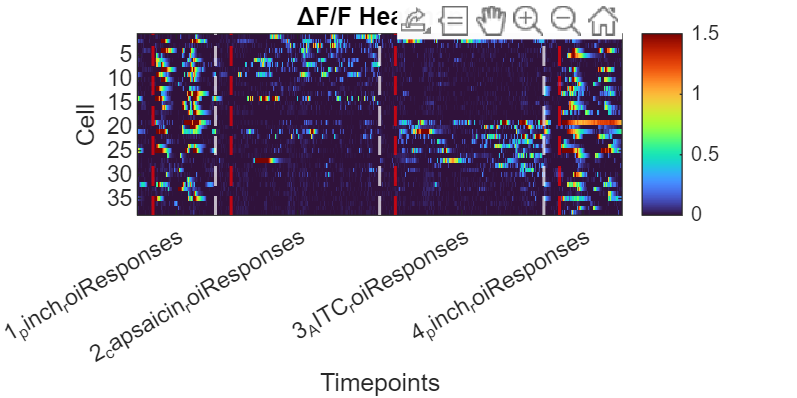

threshold = 0.5; %intensity
nstd = 5;
duration_threshold = 5; %in sec, for plotting response duration difference
all_data = vertcat(datatable(:).dataABC);
% response_metric = std(all_data);  % 1 × 25
% [~, sortIdx] = sort(response_metric, 'descend');
% sorted_data = all_data(:, sortIdx);
% Max_sorted = sort(max(sorted_data));
% Step 1: Get responses from stimulus 2 and 3

% std2_baseline = std(datatable(Sorting_stim(1)).dataABC(1:100,:)', [], 2);
% std3_baseline = std(datatable(Sorting_stim(2)).dataABC(1:100,:)', [], 2);

%resp2 = mean(datatable(Sorting_stim(1)).dataABC', 2); %max(datatable(Sorting_stim(1)).dataABC', [], 2)./std2_baseline;   % Cells x 1 (max response per cell)
%resp3 = mean(datatable(Sorting_stim(2)).dataABC', 2); %max(datatable(Sorting_stim(2)).dataABC', [], 2)./std3_baseline;   % Cells x 1
numStim = numel(datatable);
numCells =  size(datatable(1).dataABC, 2);  
response_duration = zeros(numCells, numStim);
for i = 1:numStim
    stim_lengths(i) = size(datatable(i).dataABC, 1);  % time length of each
    eachstim_data = datatable(i).dataABC;
    baseline_std = std(eachstim_data(1:100, :), 0, 1);
    baseline_mean = mean(eachstim_data(1:100,:), 1); 
    isAbove = eachstim_data >= (baseline_mean + nstd*baseline_std);%isAbove = eachstim_data >= (mean(datatable(i).dataABC', 2)'+nstd*std(datatable(i).dataABC(1:100,:)', [], 2)');%threshold;
    response_duration(:, i) = sum(isAbove, 1)'/datatable(i).framerate;
end

resp2 = response_duration(:,Sorting_stim(1));
resp3 = response_duration(:,Sorting_stim(2));
% resp2 = max(datatable(Sorting_stim(1)).dataABC', [], 2);
% resp3 = max(datatable(Sorting_stim(2)).dataABC', [], 2);
% % Step 2: Lexicographic sorting (first by resp2, then by resp3)
% [~, sortIdx] = sortrows([resp2 resp3], [-1 -1]);  % Descending for both
% sorted_data = all_data(:, sortIdx);
% Max_sorted = sort(max(sorted_data));

% Step 2: Split into two groups
idx_high = find(resp2 >= resp3);  % threshold);  % High responders to stimulus 2
idx_low = find(resp2 < resp3);    % Low responders to stimulus 2


% Step 3: Sort high group by stimulus 2 (descending)
[~, subIdx_high] = sort(resp2(idx_high), 'descend');
sorted_high = idx_high(subIdx_high);

% Step 4: Sort low group by stimulus 3 (descending)
[~, subIdx_low] = sort(resp3(idx_low), 'descend');
sorted_low = idx_low(subIdx_low);

% Step 5: Concatenate final sort order
sortIdx = [sorted_high; sorted_low];  % Combined index list

sorted_data = all_data(:,sortIdx);
Max_sorted = sort(max(sorted_data));

stim_boundaries = cumsum(stim_lengths);
stim_boundaries_2 = cumsum(stim_lengths)+100;

if size(sorted_data,2)>4
    MaxLimit = mean(Max_sorted(end-4:end));
else
    MaxLimit = max(Max_sorted);
end

if MaxLimit > 1.5 || MaxLimit < 0.2
    Limit = 1.5;
else
    Limit = MaxLimit;
end

% Limit = 1.5;


% Plot heatmap
close all
fig1 = figure('Name','dF/F Heatmap','NumberTitle', 'off');
set(fig1, 'Units', 'pixels', 'Position', [100, 100, 1600, 800]);
nCells = size(sorted_data, 2);
nTime = size(sorted_data, 1);
imagesc(1:nTime, 1:nCells, sorted_data'); % rows = cells, columns = timepoints
colormap turbo;
colorbar;
caxis([0 Limit]);

%xticks(timelength/2 + (0:numStim-1)*timelength);
xticks(stim_lengths/2 + [0 cumsum(stim_lengths(1:end-1))]);
%labels = {datatable.name};
%labels = arrayfun(@(x) extractBetween(x.name, 'm1648_', '_new'), datatable);
labels = {datatable.name};
labels_new = erase(labels, '.csv');
xticklabels(string(labels_new));
yticks(5:5:nCells);
xlabel('Timepoints');
ylabel('Cell');
title('ΔF/F Heatmap');
axis tight;

hold on;
for i = 1:numStim-1
    %xline(i * timelength + 0.5, 'w--', 'LineWidth', 1.2);
    xline(stim_boundaries(i), 'w--', 'LineWidth', 1.2);
    xline(stim_boundaries_2(i), 'r--', 'LineWidth', 1.2);
end
xline(100, 'r--','LineWidth', 1.2);

hold off;

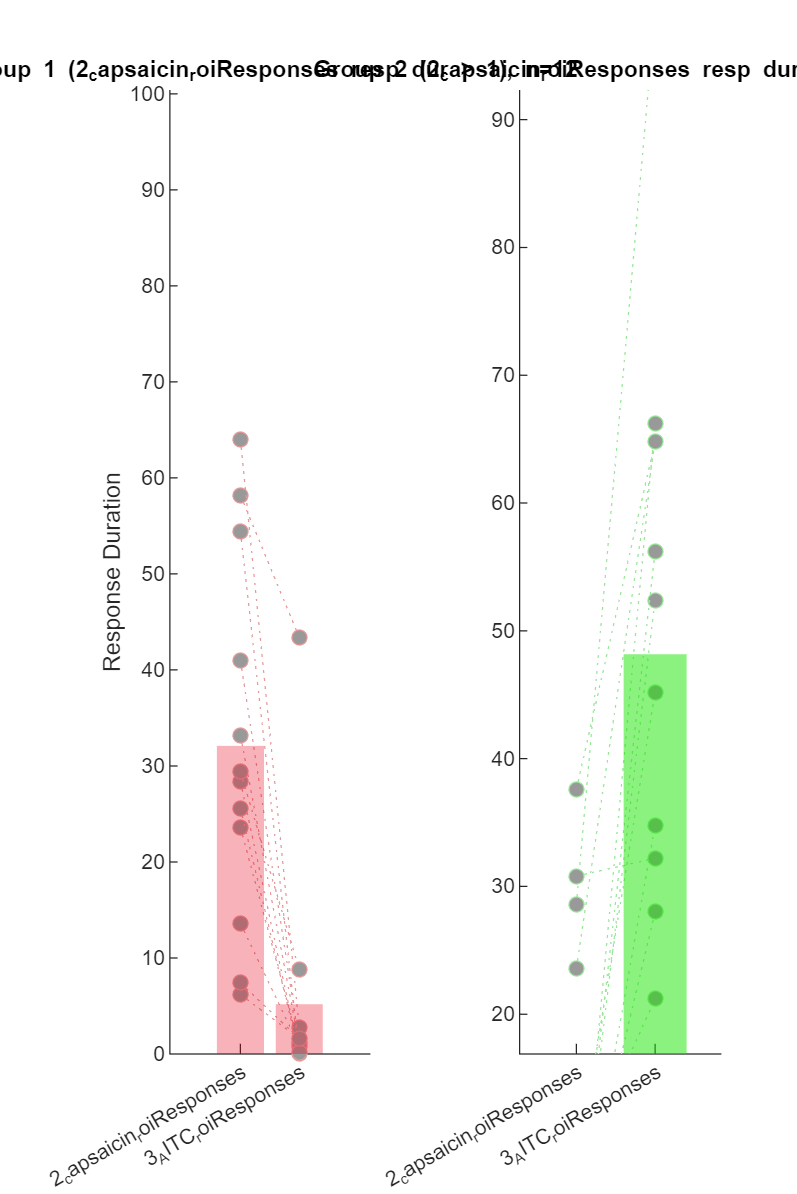


% plot response duration
stim2 = response_duration(:, Sorting_stim(1));
stim3 = response_duration(:, Sorting_stim(2));
subgroup_mask = stim2 > duration_threshold | stim3 > duration_threshold;
subgroup_idx = find(subgroup_mask);

group1_idx = subgroup_idx(stim2(subgroup_idx) > stim3(subgroup_idx));
group2_idx = subgroup_idx(stim2(subgroup_idx) <= stim3(subgroup_idx));

group1_data = response_duration(group1_idx, Sorting_stim);  % rows = cells
group2_data = response_duration(group2_idx, Sorting_stim);
xlabels = {datatable(Sorting_stim).name};
xlabels = erase(xlabels, '.csv');

fig2 = figure('Name','Barplot','NumberTitle', 'off');
set(fig2, 'Units', 'pixels', 'Position', [100, 100, 800, 1200]);
subplot(1,2,1);
hold on;
x = [1, 2];
for i = 1:size(group1_data, 1)
    plot(x, group1_data(i, :), 'o:', 'Color', [0.9 0.6 0.6],'MarkerFaceColor', [0.6 0.6 0.6]);
end
% Plot mean as bar
bar(x, mean(group1_data, 1), 'FaceColor', [0.9,0,0.1],'FaceAlpha', 0.3, 'EdgeColor', 'none');
title(sprintf('Group 1 (%s resp dur > 1), n=%d', xlabels{1}, size(group1_data,1)));
ylabel('Response Duration');
xticks(x);
xticklabels(xlabels);
ylim([0, max(response_duration(:)) + 2]);

subplot(1,2,2);
hold on;
for i = 1:size(group2_data, 1)
    plot(x, group2_data(i, :), 'o:', 'Color', [0.6 0.9 0.6],'MarkerFaceColor', [0.6 0.6 0.6]);
end
bar(x, mean(group2_data, 1), 'FaceColor', [0.1,0.9,0],'FaceAlpha', 0.5, 'EdgeColor', 'none');
title(sprintf('Group 2 (%s resp dur ≤ 1), n=%d', xlabels{1}, size(group2_data,1)));
xticks(x);
xticklabels(xlabels);
ylim([0, max(response_duration(:)) + 2]);

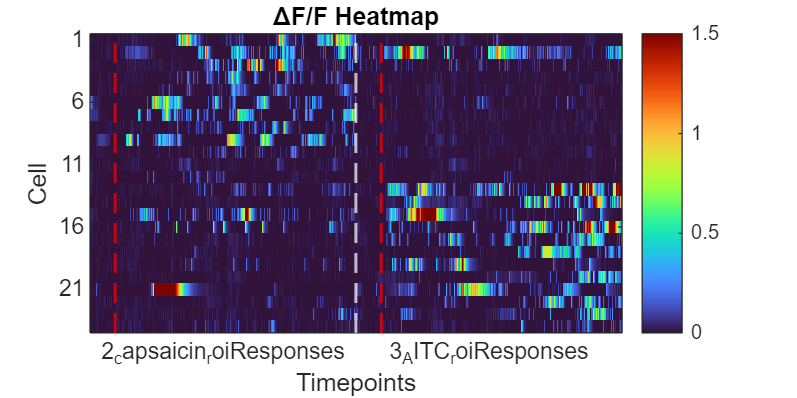


%plot heatmap of capsaicin and AITC only
[~, g1_sort] = sort(stim2(group1_idx), 'descend');
[~, g2_sort] = sort(stim3(group2_idx), 'descend');
sorted_g1_idx = group1_idx(g1_sort);
sorted_g2_idx = group2_idx(g2_sort);
final_sorted_idx = [sorted_g1_idx; sorted_g2_idx];
final_sorted_data = [];
for i = 1:numel(Sorting_stim)
    final_sorted_data = [final_sorted_data; datatable(Sorting_stim(i)).dataABC(:, final_sorted_idx)];
end
fig3 = figure('Name','dF/F Heatmap of chemicals only','NumberTitle', 'off');
set(fig3, 'Units', 'pixels', 'Position', [100, 100, 1600, 800]);
nCells = size(final_sorted_data, 2);
nTime = size(final_sorted_data, 1);
imagesc(1:nTime, 1:nCells, final_sorted_data'); % rows = cells, columns = timepoints
colormap turbo;
colorbar;
caxis([0 Limit]);

%xticks(timelength/2 + (0:numStim-1)*timelength);
xticks(stim_lengths(Sorting_stim)/2 + [0 cumsum(stim_lengths(Sorting_stim(1:end-1)))]);
%labels = {datatable.name};
%labels = arrayfun(@(x) extractBetween(x.name, 'm1648_', '_new'), datatable);
xticklabels(xlabels);
yticks(1:5:nCells);
xlabel('Timepoints');
ylabel('Cell');
title('ΔF/F Heatmap');
axis tight;
hold on;
stim_boundaries = cumsum(stim_lengths(Sorting_stim));
stim_boundaries_2 = cumsum(stim_lengths(Sorting_stim)) +100;
for i = 1:numel(Sorting_stim)-1
    %xline(i * timelength + 0.5, 'w--', 'LineWidth', 1.2);
    xline(stim_boundaries(i), 'w--', 'LineWidth', 1.2);
    xline(stim_boundaries_2(i), 'r--', 'LineWidth', 1.2);
end
xline(100, 'r--','LineWidth', 1.2);

hold off;

% Max_over = sort(max(OverlapData)); 
% if size(OverlapData,2)>4
%     MaxLimit = mean(Max_non(end-4:end));
% else
%     MaxLimit = max(Max_non);
% end
% 
% if MaxLimit > 1.5 || MaxLimit < 0.2
%     Limit = 1.5;
% else
%     Limit = MaxLimit;
% end
% 
% figure;
% imagesc(OverlapData');
% colormap turbo;
% colorbar;
% caxis([0 Limit]);
% xlabel('Timepoints');
% ylabel('overlapping Cell Index');
% title(['ΔF/F Heatmap for Overlapping Cells: ', datatable(i).name]);

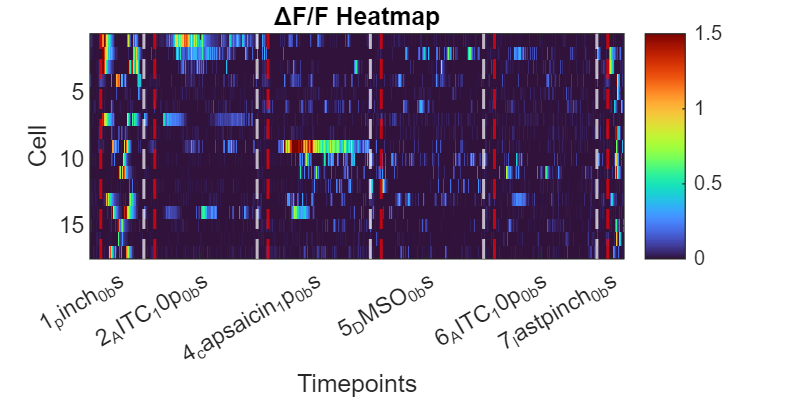

heatmap_name = 'Heatmap Plot of cell responses.pdf';
bargraph_name = 'Response duration comparison.pdf';
filtered_heatmap_name = 'Heatmap Plot of cell responding to chemicals.pdf';
heatmap_path = fullfile(pathName,heatmap_name);
bargraph_path = fullfile(pathName,bargraph_name);
filtered_heatmap_path = fullfile(pathName,filtered_heatmap_name);
exportgraphics(fig1, heatmap_path, 'ContentType', 'vector');

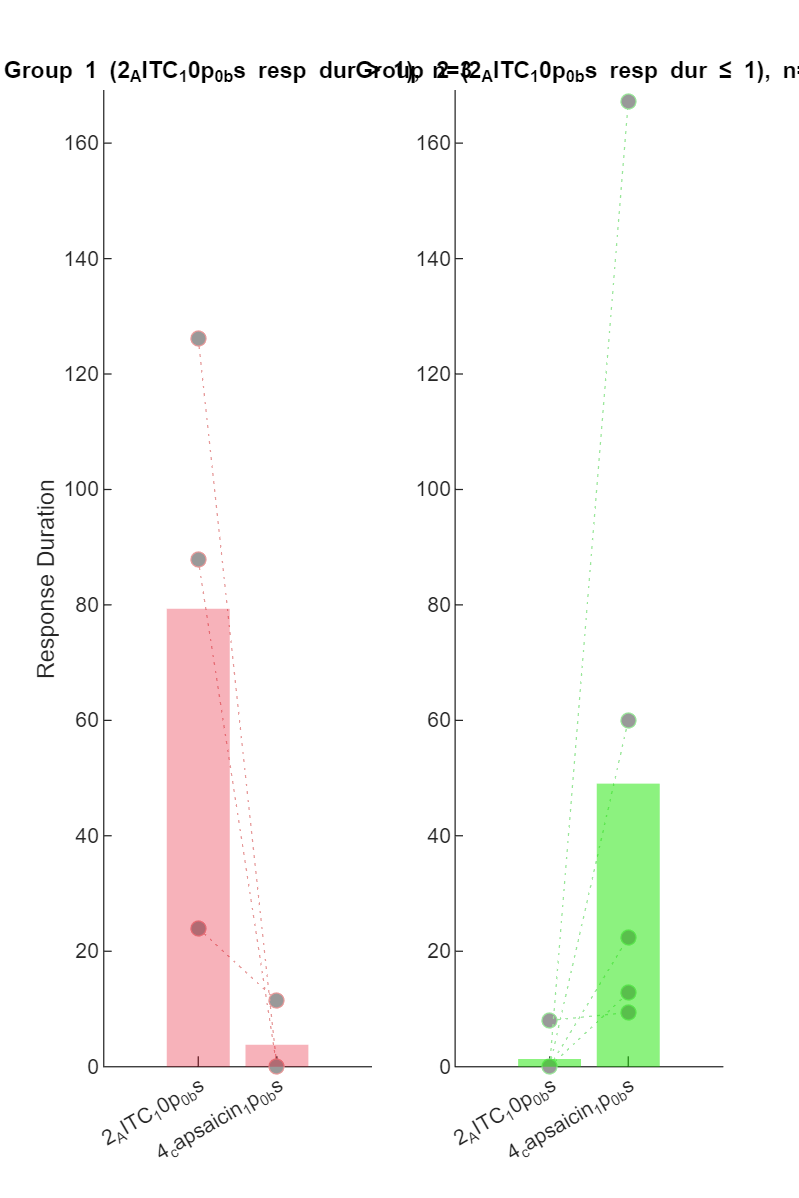

exportgraphics(fig2, bargraph_path, 'ContentType', 'vector');

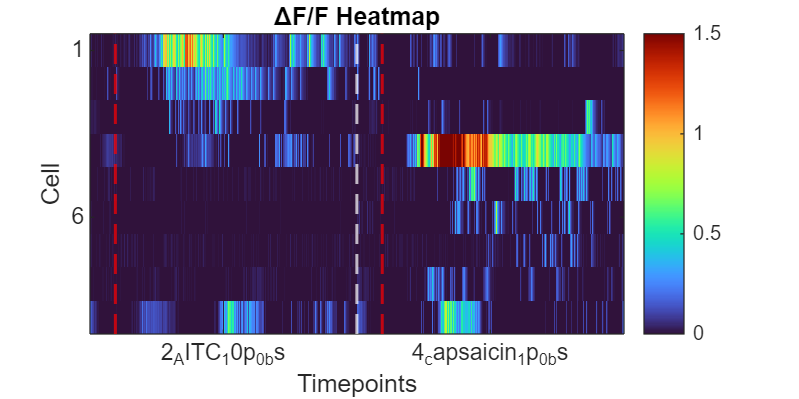

exportgraphics(fig3, filtered_heatmap_path, 'ContentType', 'vector');

filename_output = strcat(extractBetween(pathName, 'calcium\', '\preprocess'), '_datatable.mat');
filename_output = filename_output{1};
sortedfilename_output = strcat(extractBetween(pathName, 'calcium\', '\preprocess'), '_final_sorted_data.mat');
sortedfilename_output = sortedfilename_output{1};

save(fullfile(pathName, filename_output), 'datatable');
save(fullfile(pathName, sortedfilename_output), 'final_sorted_data')

%Stuff below are test codes used before
% Step 1: Get responses from stimulus 2 and 3
resp2 = max(datatable(2).dataABC', [], 2);   % Cells x 1 (max response per cell)
resp3 = max(datatable(3).dataABC', [], 2);   % Cells x 1

% Step 2: Lexicographic sorting (first by resp2, then by resp3)
[~, sortIdx] = sortrows([resp2 resp3], [-1 -1]);  % Descending for both

% Step 3: Concatenate all stimuli (transpose for cells x time)
numStim = numel(datatable);
data_per_stim = cell(1, numStim);
stim_lengths = zeros(1, numStim);
for i = 1:numStim
    data_per_stim{i} = datatable(i).dataABC';  % 63 x time
    stim_lengths(i) = size(data_per_stim{i}, 2);
end

% Step 4: Combine and sort
all_data = horzcat(data_per_stim{:});% 63 x total_time
sorted_data = all_data(:, sortIdx);         % Apply sort order

% Step 5: Plot
imagesc(sorted_data');
colormap(turbo);
colorbar;
caxis([0 1.5]);
axis xy;
axis tight;
xlabel('Time (frames)');
ylabel('Cell (sorted by Stim 2, then Stim 3)');
title('Heatmap: Cells Sorted by Stimulus 2, Then Stimulus 3');

% Step 6: Add stimulus boundaries
hold on;
stim_boundaries = cumsum(stim_lengths);
for i = 1:numStim-1
    xline(stim_boundaries(i)+0.5, 'w--', 'LineWidth', 1.2);
end

% Step 7: Add labels
xticks(stim_lengths/2 + [0 cumsum(stim_lengths(1:end-1))]);
xticklabels(erase({datatable.name}, '.csv'));
xtickangle(45);



png_name = 'Heatmap Plot of cell responses.png';
png_path = fullfile(pathName,png_name);
exportgraphics(fig(2), png_path, 'Resolution', 300);

#### If happy with the figure, save it

if (1)
    pathparts = strsplit(path,filesep);
    mouseID = pathparts{end-1}; clear pathparts
    name = [filename(1:end-4), '_', mouseID];
    t = title(name);
    set(t,'Interpreter','none')
    
    figureName = [path, name, '.jpg'];
    saveas(gcf,figureName)
    clear t
end

#### Save into structure called 'Data'

save the data into structure so it's easier to access in the future

% structName = [path, 'Data.mat'];
% if isfile(structName)
%     load(structName);
% else
%     Data = struct;
%     %data.info.mouseID = mouseID;
% end
% 
% if contains(filename,"frey")  % the fieldname can't start with number
%     filename = erase(filename, "von_frey");
%     filename = strcat('von_frey',filename);    
% end
% 
% Data.(filename(1:end-4)) =  normDeltaF;
% 
% 
% save(structName, 'Data');
% 
% clear structName

TableName = [path, 'Data.mat'];



#### Quatification and save the responsive ROIs into a structure

nStd = 3;%7; 
% the signal that is 'nStd' times of of standard deviation larger than noise (in baseline) is regarded as response 
% nStd can change depending on the sigal-to-noise ratio of imaging
% the baseline is the first 90 or 100 frames of the imaging averaged

%[digitROI, responseROI0] = quantify(normDeltaF, filename, nStd);

[digitROI, responseROI0] = quantify(nonOverlapData, fileNames{i}, nStd);

#### Plot traces of all responsive neurons

thresh = 0.1; 
spike0 = plotAllResponse(responseROI0, normDeltaF,path, filename, thresh, fps, ...
    "peakLabel", 1, 'NumFig', 60, 'save',0); 
% if "peakLabel" is 1, peaks will be labeled
% the spike0 contains the amplitude and timing of the peaks

#### Save the response information into two structure

% goodROI = [1, 2, 5, 7, 8, 10, 11, 20, 21, 24, 25, 26, 27 ]; badROI = setdiff(responseROI0, goodROI);
badROI = [];
[responseROI, responseIndex] = setdiff(responseROI0, badROI);
responseROI(2, :) = nStd; % nStd means the definition of response, stored in second line of responseROI
responseROI(3, 1:length(badROI)) = badROI;
spike = spike0(:, responseIndex,:);
% clear spike0 responseROI0

responseStructName = [path, 'responseROIstruct.mat'];
if isfile(responseStructName)
    load(responseStructName);
else
    responseROIstruct = struct;
end

responseROIstruct.(filename(1:end-4)) = responseROI;
% responseROIstruct.(filename(1:end-5)) = responseROI;

save(responseStructName, 'responseROIstruct');

spikeStructName = [path, 'spikeStruct.mat'];
if isfile(spikeStructName)
    load(spikeStructName);
else
    spikeStruct = struct;
end

spikeStruct.(filename(1:end-4)) = spike;
save(spikeStructName, 'spikeStruct');

#### Plot traces of certain neuron (optional)

If curious about what certain trace looks like, or what does bleach correction algorithm do to the trace


nCell = input('the neuron you are interesed in?  \n ');
figure,
subplot(211);
plot(normDeltaF(:,nCell)), title(['DeltaF/F of Cell ', num2str(nCell)]);
box off
% subplot(212),findpeaks(normDeltaF(:,nCell),'MinPeakProminence',thresh),title('Peaks');
[~, b, ~] = RobustDetrend(normDeltaF(:,nCell), 6, 0.975);
subplot(212), plot(b), 
title(['DeltaF/F of Cell ', num2str(nCell), ' bleach corrected']);
box off
